clear;
for i = 1:3
    for j = 1:3
        for k = 1:5
            A(k,i,j) = i + 2*j;
        end
    end
end

A

A = A(:,:,1) =

     3     4     5
     3     4     5
     3     4     5
     3     4     5
     3     4     5


A(:,:,2) =

     5     6     7
     5     6     7
     5     6     7
     5     6     7
     5     6     7


A(:,:,3) =

     7     8     9
     7     8     9
     7     8     9
     7     8     9
     7     8     9



B = reshape(A,[],5)

B =      3     4     5     7     8
     3     5     5     7     8
     3     5     6     7     8
     3     5     6     7     8
     3     5     6     7     9
     4     5     6     7     9
     4     5     6     7     9
     4     5     7     7     9
     4     5     7     8     9


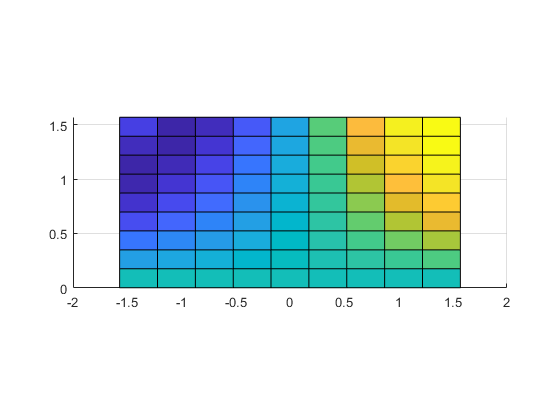


clear;
M = 10;
N = 10;
orig_dom_X1 = linspace(-pi/2,pi/2,M);
orig_dom_Y1 = linspace(0,pi/2,N);
[X,Y] = ndgrid(orig_dom_X1,orig_dom_Y1);

for k = 1:88
    m = rand;
    b = rand;
    A(k,:,:) = m*sin(X.*Y) + b;
end
surf(X,Y,squeeze(A(5,:,:)))
daspect([1 1 1])
view(2)


s = size(A);

B = reshape(A,[],s(1))

B =     0.5587    0.7482    0.5359    0.6217    0.6968    0.3879    0.4938    0.8048    0.5332   -0.0087    0.4367    0.4855    0.2679    0.1860    0.2853    1.0276    0.1909    0.8451    0.1028    0.0180    0.0941    0.4586    0.5841    0.9279    0.5509    0.8961    1.1829   -0.2036    0.3506    0.6899    0.4458    0.1991    0.8628    1.0242    0.3533    0.6196   -0.3305    0.3931    0.0272    0.7905    0.6835    0.0333    0.1330    1.0255    0.1497   -0.1174    0.5014    0.3290    0.5553    0.5103
    0.1981    0.7893    0.5149    0.9495    0.7555    0.7471    0.8290    0.6395    0.3155    0.5402    0.1900    0.9270    0.9161    0.7361    0.3721    0.0520    0.6829    0.2730    0.6156    0.2345    0.6453    0.9309    0.2066    0.8403    0.7140    0.9970    0.7899    0.1143    0.4589    0.5541    0.2524    0.7535    0.5522    0.9364    1.3193    0.9287    0.3111   -0.0096    0.6719    0.1170    0.6175    0.2563    0.8421    1.2277    0.0605    0.5438    0.0568    0.8989    0.7454    0

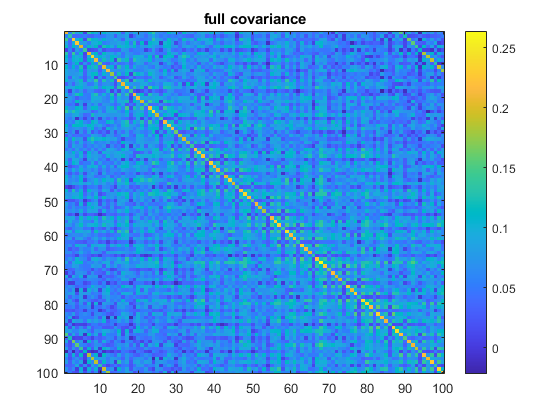

B = B';

C_B = cov(B);
imagesc(C_B)
colorbar
title('full covariance')

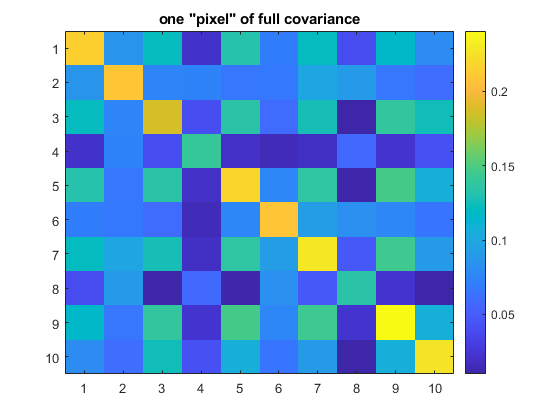


imagesc(C_B((end-M+1):end,(end-M+1):end))
colorbar
title('one "pixel" of full covariance')

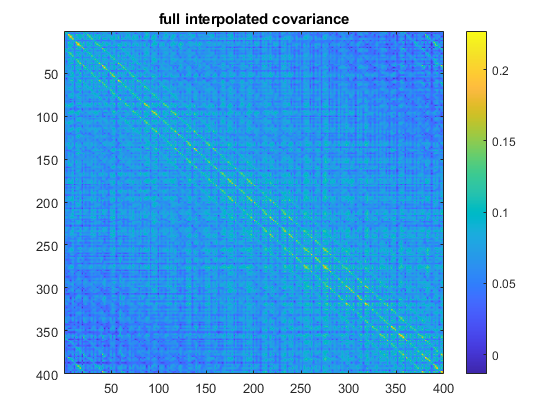


N_h = 20;
M_h = 20;

new_dom_X1 = linspace(-pi/2,pi/2,N_h);
new_dom_Y1 = linspace(0,pi/2,N_h);
new_dom_X2 = linspace(-pi/2,pi/2,M_h);
new_dom_Y2 = linspace(0,pi/2,M_h);

[X1_h,Y1_h] = ndgrid(new_dom_X1,new_dom_Y1);
wv_1 = reshape(permute(cat(3,X1_h,Y1_h),[3 1 2]),2,[]);
% disp('size(wv_1,2)')
% size(wv_1,2)

[X2_h,Y2_h] = ndgrid(new_dom_X2,new_dom_Y2);
wv_2 = reshape(permute(cat(3,X2_h,Y2_h),[3 1 2]),2,[]);
% disp('size(wv_2,2)')
% size(wv_2,2)

C_B_high_def = covariance_function(wv_1',wv_2',orig_dom_X1,orig_dom_Y1,C_B);

imagesc(C_B_high_def)
colorbar
title('full interpolated covariance')

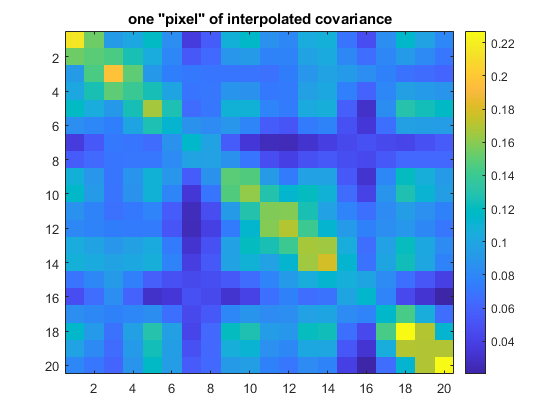


imagesc(C_B_high_def((end-N_h+1):end,(end-M_h+1):end))
colorbar
title('one "pixel" of interpolated covariance')